tiqu = readtable('tiqu.csv')

tiqu = 68×9 table
    Num     x2      x3    x4    temp    water    x7     y1      y2 
    ___    _____    __    __    ____    _____    ___    ___    ____

     3     30.17    35    30     75     6360     187      6    5.36
     2     32.14    35    25     80     6360     187      7    8.32
     1     31.66    35    27     75     6360     187    6.5    7.18
     3     29.35    35    30     71     6360     187      6    5.17
     1     29.29    35    33     71     6360     187    5.5    5.66
     2     28.75    35    35     65     6360     187    4.5    4.78
     1      30.1    35    30     72     6360     187    5.5    5.81
     3     29.18    35    33     65     6360     187    5.5    

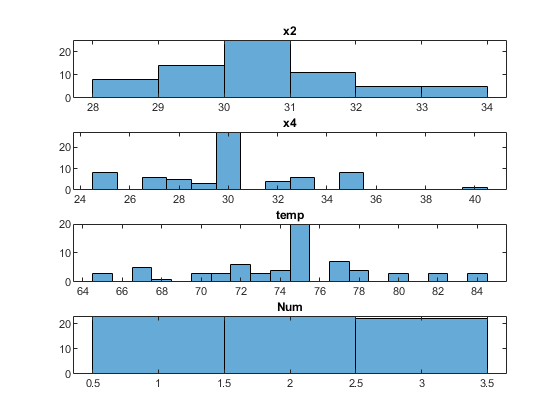

subplot(4,1,1)
histogram(tiqu{:,"x2"});
title("x2");
% x4
subplot(4,1,2)
histogram(tiqu{:,"x4"});
title("x4");
%temp
subplot(4,1,3)
histogram(tiqu{:,"temp"});
title("temp");

subplot(4,1,4)
histogram(tiqu{:,"Num"});
title("Num");

SampleNum = 300;
sz = [SampleNum,1];

## gen fake stream

Num = randi(3,sz);
% norm fit
[mu,sigma] = normfit(tiqu{:,"x2"});
x2 = normrnd(mu,sigma,sz);
Counts = tabulate(tiqu{:,'x4'})
noZeroIndex = Counts(:,2)>0;
s = RandStream('mlfg6331_64'); 
x4 = datasample(s,Counts(1,noZeroIndex),SampleNum,'Weights',Counts(3,noZeroIndex));

Counts = tabulate(tiqu{:,'temp'})
noZeroIndex = Counts(:,2)>0;
x4 = datasample(s,Counts(1,noZeroIndex),SampleNum,'Weights',Counts(3,noZeroIndex));
% 新建一个空的dataFrame
types = {'double','double','double','double','double','double','double'};
names = tiqu.Properties.VariableNames(1:7);
fake_Gen = table("Size",[SampleNum,7],'VariableTypes',types,"VariableNames",names);
fake_Gen{:,""}